# **Eksamen M4STI1 2019F**

### Løsningsforslag af Allan Leck Jensen

### Opgave 1 - Sorteringseffektivitet

Oplysninger i opgaven:

clear; close all; clc; format compact;
n_VH = 885              % Antal stykker hårdt plastik, der skal sorteres

n_VH = 885

n_VB = 313              % Antal stykker blødt plastik, der skal sorteres

n_VB = 313

n_total = n_VH + n_VB   % Antal stykker plastik ialt. 

n_total = 1198


n_SH = 738              % Antal stykker plastik, der blev sorteret som hårdt

n_SH = 738

n_SB = n_total - n_SH   % Antal stykker plastik, der blev sorteret som blødt

n_SB = 460


n_VH_n_SH = 732     % Antal stykker hårdt plastik, der er sorteret som hårdt 

n_VH_n_SH = 732

                    % Jeg bruger n som tegnet for fælleshændelse, så (VH n SH) betyder 
                    % at plastikstykket er både hårdt i virkeligheden og sorteret som hårdt
n_VB_n_SB = 307     % Antal stykker blødt plastik, der også er sorteret som blødt

n_VB_n_SB = 307

Tallene kan stilles op i en tabel for at få overblik (jeg har lavet den i Excel):

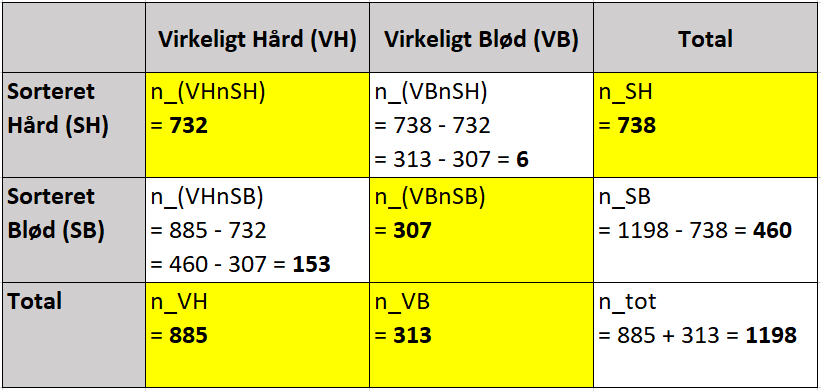

Tallene med gul baggrund er oplyste, dem med hvid baggrund er beregnet. 

#### a. Beregn sandsynlighederne P(*VH*), P(*VB*), P(*SH*) og P(*SB*) for kassens indhold.

Sandsynligheden for, at et tilfældigt stykke plastik er hårdt i virkeligheden, beregnes som antal stykker plastik, der er hårde i virkeligheden (n_VH = 885) delt med det totale antal plastikstykker (n_total = 1198). Det giver P_VH = 0.7387. De andre sandsynligheder beregnes tilsvarende:

P_VH = n_VH/n_total     

P_VH = 0.7387

P_VB = n_VB/n_total     

P_VB = 0.2613

P_SH = n_SH/n_total     

P_SH = 0.6160

P_SB = n_SB/n_total     

P_SB = 0.3840

#### b. Beregn sandsynlighederne P(*VH* | *SH*) og P(*VB* |*SB*)

Sandsynligheden for at et stykke plastik i virkeligheden er hårdt, når det er blevet sorteret som hårdt (P_VH_givet_SH), beregnes som antal stykker plastik, der er hårde i virkligheden blandt de stykker, der er blevet sorteret som hårde  (n_VH_n_SH = 732), delt med antal stykker, der er blevet sorteret som hårde (n_SH = 738). Det giver P_VH_givet_SH = 0.9919, så over 99 % af det  plastik, der er sorteret som hårdt, er hårdt i virkeligheden. Tilsvarende findes P_VH_givet_SH = 0.6674, så kun godt 2/3 af det plastik, der er sorteret som blødt, er blødt i virkeligheden.  

Den formel, der bruges er $P\left(A\;|\;B\right)=\frac{P\left(A\cap B\right)}{P\left(B\right)}$

P_VH_givet_SH = n_VH_n_SH / n_SH     

P_VH_givet_SH = 0.9919

P_VB_givet_SB = n_VB_n_SB / n_SB     

P_VB_givet_SB = 0.6674

#### c. Beregn sandsynlighederne P(*VB* | *SH*) og P(*VH* |*SB*)

Hændelsen at plastik sorteres forkert er det komplementære til at det sorteres korrekt.  

P_VB_givet_SH = 1 - P_VH_givet_SH     

P_VB_givet_SH = 0.0081

P_VH_givet_SB = 1 - P_VB_givet_SB     

P_VH_givet_SB = 0.3326

Alternativt kan de to sandsynligheder beregnes med samme metode som i delopgave b:

n_VB_n_SH = n_SH - n_VH_n_SH

n_VB_n_SH = 6

n_VH_n_SB = n_VH - n_VH_n_SH

n_VH_n_SB = 153

P_VB_givet_SH = n_VB_n_SH / n_SH     

P_VB_givet_SH = 0.0081

P_VB_givet_SB = n_VH_n_SB / n_SB

P_VB_givet_SB = 0.3326

#### d. Andelen af hårdt plastik i ny kasse, P(*VH*)

I den nye kasse bliver 78 % sorteret som hårdt. Dermed bliver 22 % sorteret som blødt. 

P_SH_ny = 0.78

P_SH_ny = 0.7800

P_SB_ny = 1 - P_SH_ny

P_SB_ny = 0.2200

Ifølge loven om den totale sandsynlighed: Det plastik, der er hårdt i virkeligheden, består af to grupper: 1) det, der er sorteret korrekt som hårdt plus 2) det, der er sorteret forkert som blødt (og som derfor i virkeligheden er hårdt): 

        P_VH_ny = P_VH_givet_SH_ny * P_SH_ny + P_VH_givet_SB_ny * P_SB_ny

Vi antager, at de betingede sandsynligheder er de samme for den nye kasse som for den oprindelige:

        P_VH_givet_SH_ny = P_VH_givet_SH = 0.9919

        P_VH_givet_SB_ny = P_VH_givet_SB = 0.6674

Derfor:

P_VH_ny = P_VH_givet_SH * P_SH_ny + P_VH_givet_SB * P_SB_ny

P_VH_ny = 0.8468

Knap 85 % af plastikken i den nye kasse er altså hårdt. 

#### e. Beregn sandsynligheden for at et hårdt stykke plastik fra den nye kasse bliver sorteret korrekt, P(SH | VH)

Sandsynligheden P(SH |VH) kan beregnes med Bayes' formel:

        P_SH_givet_VH = P_VH_givet_SH * P_SH_ny / P_VH_ny

P_SH_givet_VH = P_VH_givet_SH * P_SH_ny / P_VH_ny

P_SH_givet_VH = 0.9136

 Godt 94 % af det hårde plastik i den nye kasse bliver sortertet korrekt. 

### **Opgave 2  –  Optimering af maskinens opsætning**

#### **Indlæsning af data**

clear; close all; clc; format compact;
D = xlsread('Data_M4STI1_2019F.xlsx', 'A:C');

vinkel = D(:,1);     % Vinkel på pladerne, der skal sortere plastikken
rothast = D(:,2);    % Rotationshastighed for pladerne
effekt = D(:,3);     % Sorteringseffektivitet
n = size(D,1)       % Antal observationer i datasættet

n = 20

### a. Lav et scatterplot af sorteringseffektivitet E over for henholdsvis vinkel theta og rotationshastighed omega. Diskutér, om der lader til at være en sammenhæng mellem den enkelte regressor og responsvariablen.

**Afhængighed mellem vinkel og sorteringseffektivitet**

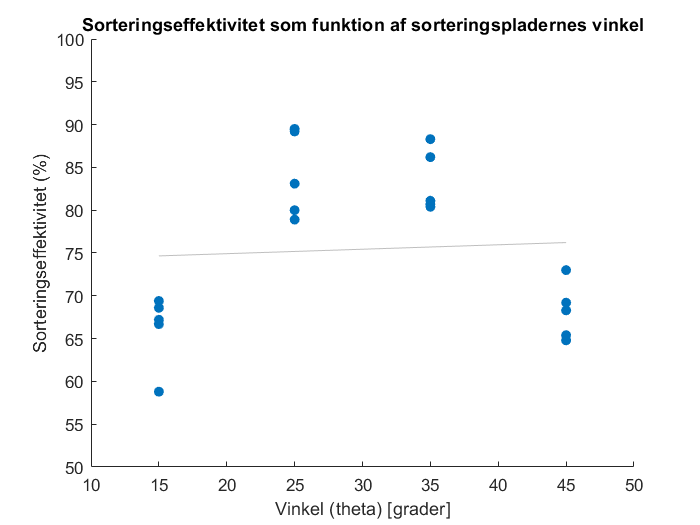

figure(1)
scatter(vinkel, effekt, 'filled')
lsline
title('Sorteringseffektivitet som funktion af sorteringspladernes vinkel')
xlabel('Vinkel (theta) [grader]')
ylabel('Sorteringseffektivitet (%)')
axis([10, 50, 50, 100])

Der lader til at være en sammenhæng mellem vinkel og sorteringseffekt, men den er ikke lineær. Sorteringseffektiviteten er høj ved 25 og 35 grader, men lav ved 15 og 45 grader. Formodentlig er en polynomiel sammenhæng bedre.

**Afhængighed mellem rotationshastighed og sorteringseffektivitet**

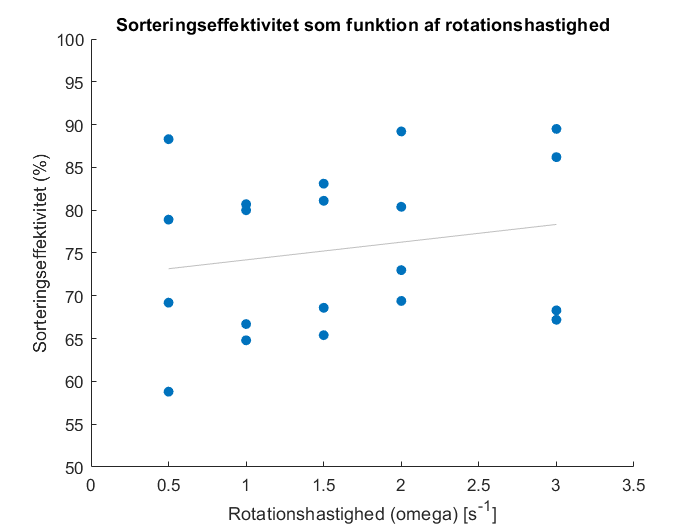

figure(2)
scatter(rothast, effekt, 'filled')
lsline
title('Sorteringseffektivitet som funktion af rotationshastighed')
xlabel('Rotationshastighed (omega) [s^{-1}]')
ylabel('Sorteringseffektivitet (%)')
axis([0, 3.5, 50, 100])

Der lader til at være en positiv korrelation mellem rotationshastighedog sorteringseffekt, men den er meget svag. 

#### b. Lav en multipel lineær regressionsmodel, der beskriver sorteringseffektiviteten som funktion af vinkel theta og rotationshastighed omega. Skriv ligningen op. 

mdl = fitlm([vinkel, rothast], effekt, 'PredictorVars', {'vinkel', 'rothast'}, 'ResponseVar','effekt')

mdl = Linear regression model:
    effekt ~ 1 + vinkel + rothast

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________
    (Intercept)      70.57      7.3798     9.5626    2.9704e-08
    vinkel           0.052     0.19331      0.269       0.79117
    rothast         2.0689      2.5124    0.82348       0.42164

Number of observations: 20, Error degrees of freedom: 17
Root Mean Squared Error: 9.67
R-squared: 0.0423,  Adjusted R-Squared -0.0704
F-statistic vs. constant model: 0.375, p-value = 0.693

Regressionsligning:

        effekt = 70.57 + 0.052*vinkel + 2.0689*rothast

#### c. Forklar vha. regressionsanalysens statistikker (f.eks. R-squared, F og p-value), om modellen beskriver observationerne godt

Modellen er dårlig til at beskrive data. Det er kun koefficienten b0 = 70.57 (dvs. skæringen med y-aksen), der er signifikant forskellig fra 0. Både b1 = 0.052 og b2 = 2.0689 har høje p-værdier (hhv. 0.79 og 0.42), så de kunne lige så godt være 0. Der er altså ingen signifikant korrelation. 

Det samme resultat kommer af ANOVA testen. F-teststørrelsen er 0.375 og den tilhørende p-værdi er 0.693, så både b1 og b2 kan sagtens være 0 samtidig. 

R-squared = 0.0423 fortæller ligeledes, at modellen er dårlig, da den kun beskriver 4 % af variationen i data. 

#### d. Udvid modellen, så du inddrager kvadratled og interaktionsled. Fjern de led, som du ikke mener er nødvendige i modellen, og begrund dine valg.

Jeg udvider modellen med kvadratled og interaktionsled vha. Wilkinson notation:

mdl1 = fitlm([vinkel, rothast], effekt, 'y ~ x1 + x2 + x1^2 + x2^2 + x1:x2')

mdl1 = Linear regression model:
    y ~ 1 + x1*x2 + x1^2 + x2^2

Estimated Coefficients:
                   Estimate       SE         tStat        pValue  
                   ________    _________    ________    __________
    (Intercept)     0.65597       8.5642    0.076594       0.94003
    x1               5.2037      0.51642      10.076    8.5001e-08
    x2               5.9443       5.0877      1.1684       0.26217
    x1:x2           -0.1073     0.085362      -1.257       0.22933
    x1^2             -0.083    0.0082098      -10.11    8.1579e-08
    x2^2           -0.18542       1.2121    -0.15298        0.8806

Number of observations: 20, Error degrees of freedom: 14
Root Mean Squared Error: 3.67
R-squared: 0.886,  Adjusted R-Squared 0.846
F-sta

Jeg vælger et signifikansniveau på 5 %. Der er flere koefficienter, der ikke er signifikante: b2, b12 og b22 kan alle være lig 0, da de har p-værdier over 0.05. b22 = -0.18542 har den højeste p-værdi på 0.8806, så den er mindst signifikant. Den fjerner jeg fra modellen:

mdl2 = fitlm([vinkel, rothast], effekt, 'y ~ x1 + x2 + x1^2 + x1:x2')	

mdl2 = Linear regression model:
    y ~ 1 + x1*x2 + x1^2

Estimated Coefficients:
                   Estimate       SE         tStat       pValue  
                   ________    _________    _______    __________
    (Intercept)     1.0945        7.8032    0.14026       0.89032
    x1              5.2037       0.49933     10.421    2.8953e-08
    x2              5.2878        2.6424     2.0011      0.063813
    x1:x2          -0.1073      0.082536       -1.3       0.21322
    x1^2            -0.083     0.0079381    -10.456    2.7707e-08

Number of observations: 20, Error degrees of freedom: 15
Root Mean Squared Error: 3.55
R-squared: 0.886,  Adjusted R-Squared 0.856
F-statistic vs. constant model: 29.1, p-value = 6.46e-07

Nu er koefficienterne b2 og b12 ikke signifikante, selvom b2 er tæt på med p-værdi = 0.063813. Jeg fjerner leddet for interaktion, da b12 har den største p-værdi, nemlig 0.21322:

mdl3 = fitlm([vinkel, rothast], effekt, 'y ~ x1 + x2 + x1^2')

mdl3 = Linear regression model:
    y ~ 1 + x1 + x2 + x1^2

Estimated Coefficients:
                   Estimate       SE         tStat       pValue  
                   ________    _________    _______    __________
    (Intercept)     6.2447        6.8661     0.9095       0.37658
    x1               5.032       0.49182     10.231    1.9963e-08
    x2              2.0689       0.94247     2.1952      0.043246
    x1^2            -0.083     0.0081074    -10.238    1.9795e-08

Number of observations: 20, Error degrees of freedom: 16
Root Mean Squared Error: 3.63
R-squared: 0.873,  Adjusted R-Squared 0.849
F-statistic vs. constant model: 36.7, p-value = 2.11e-07

Nu er alle koefficienter for hældningskoefficienter signfikant forskellige fra 0 på 5 % signifikansniveau. R-squared er kun reduceret fra 0.886 til 0.873 fra den fulde model  til denne. Selv om plots fra delopgave a viser meget varians i data, så forklarer modellen altså 87 % af det. Samtidig er Adjusted R-Squared steget en anelse fra 0.846 til 0.849. Den model vælger jeg.

#### e. Skriv ligningen for din foretrukne model op. Beregn sorteringseffektiviteten, hvis vinklen sættes til  theta = 28 og rotationshastigheden til omega = 2.5

Modelforskrift: 

        effekt = 6.2447 + 5.032*vinkel + 2.0689*rothast - 0.083*(vinkel)^2

effekt_est = 6.2447 + 5.032 * 28 + 2.0689 * 2.5 - 0.083 * (28)^2

effekt_est = 87.2410

Alternativt kan ligningen udtrykkes som en MatLab funktion (jeg undgår at bruge navnene effekt, vinkel og rothast, for jeg vil ikke overskrive mine arrays med data, der hedder dette):

eff = @(vinkel1, rothast1) 6.2447 + 5.032*vinkel1 + 2.0689*rothast1 - 0.083 * vinkel1.^2

eff = function_handle with value:
    @(vinkel1,rothast1)6.2447+5.032*vinkel1+2.0689*rothast1-0.083*vinkel1.^2

effekt_est = eff(28, 2.5)

effekt_est = 87.2410

#### f. Giv dit mest kvalificerede bud på, hvilken vinkel, der bør vælges for sorterings-maskinen, for at opnå så høj sorteringseffektivitet som muligt.

Der er flere måder at besvare dette delspørgsmål på. En af de mest kvalificerede måder er at finde optimum ved at differentiere modeludtrykket og sætte det lig 0. Modellens forskriftl:  

        effekt = b0 + b1*vinkel + b2*rothast + b11*(vinkel)^2

Ligningen differentieres partielt mht. vinkel, sættes lig 0 og løses for at bestemme optimal værdi af vinkel:

    d(effekt)/d(vinkel) = 0 + b1 + 0 + 2*b11*vinkel = 0 =>

    vinkel = -b1/(2*b11) 

b1 = 5.032

b1 = 5.0320

b11 = -0.083

b11 = -0.0830

vinkel_opt = -b1/(2*b11)

vinkel_opt = 30.3133

Den optimale vinkel på sorteringsmaskinen er **30.3 grader**.

En alternativ (men mindre kvalificeret) løsning kunne være at aflæse den optimale vinkel i scatterplottet fra delspørgsmål a. Her lader toppunktet til at være cirka midt imellem 25 og 35 grader, altså er vinkel_opt = 30 et godt bud. 

Man kan også sætte alle heltallige værdier af vinkel fra 25 til 35 ind i ligningen fra 2.e og bestemme den vinkel med størst effekt. Men så skal man argumentere for, hvilken værdi af rotationshastighed, man kan vælge. Det er dog ligegyldigt, for der er ingen interaktion mellem vinkel og rotationshastighed (jeg har jo fjernet interaktionsleddet i fitlm, for det var ikke signifikant). Derfor er effekten maksimal for en vinkel på ca 30 grader, uanset værdien af rotationshastighed. 

#### g. Undersøg om der er unormale observationer i datasættet (outliers, løftestangs-punkter eller indflydelsespunkter).

lev = mdl3.Diagnostics.Leverage;     % hat diagonal
rst = mdl3.Residuals.Studentized;    % R-Student
nr = (1:n)';                         % Observationsnummer

Bemærk at jeg skal bruge mdl3, som gælder for min endelige model, til at finde hatdiagonaler og R-Student. Jeg samler det hele til en resultattabel (jeg laver først et array, og dernæst laver jeg arrayet om til en tabel med tabeloverskrifter. På den måde får jeg  vist alle rækkerne i rapporten):

resarray = [nr, vinkel, rothast, effekt, lev, rst];
resultat = array2table(resarray, ...
    'VariableNames',{'Nr','Vinkel','Rotationshastighed', 'Effekt', 'Leverage', 'RStudent'})

resultat = 20×6 table
    Nr    Vinkel    Rotationshastighed    Effekt    Leverage    RStudent 
    __    ______    __________________    ______    ________    _________
     1      15             0.5             58.8     0.27176       -1.8286
     2      15               1             66.7     0.21432       0.48007
     3      15             1.5             68.6     0.19068       0.73946
     4      15               2             69.4     0.20081       0.67073
     5      15               3             67.2     0.32243       -0.6773
     6      25             0.5             78.9     0.19176      -0.69538
     7      25               1               80     0.13432      -0.65156
     8      25             1.5             83.1     0.11068     -0.049024
     9      25               2    

k = 3;                  % Der er tre regressorer i min model (nemlig vinkel, rothast og (vinkel)^2)
lev_limit = 2*(k+1)/n   

lev_limit = 0.4000

Bemærk at selv om der kun er to regressorvariable i data, så har jeg 3 i min model, nemlig vinkel, rothast og (vinkel)^2.

Der er ingen løftestangspunkter, for ingen har lev > lev_limit = 0.4.

Der er ingen outliers, for ingen har |rst| > 3.

Dermed er der heller ingen indflydelsespunkter. 

### Opgave **3  –  Belægning på sorteringspladerne**

#### **Indlæsning af data**

clear; close all; clc; format compact;
D = xlsread('Data_M4STI1_2019F.xlsx', 'E:F');

effekt_opr = D(:,1)     % Sorteringseffekt med oprindelig belægning

effekt_opr =    70.3000
   86.7000
   77.9000
   75.0000
   79.7000
   73.9000
   80.9000
   78.2000
   91.9000
   86.7000


effekt_ny = D(:,2)      % Sorteringseffekt med ny belægning

effekt_ny =    78.6000
   75.6000
   86.6000
   79.2000
   81.3000
   82.7000
   81.3000
   78.3000
   79.6000
   80.6000


n = size(D,1)           % Antal sorteringer, dvs. stikprøvestørrelse

n = 24

####  a. Beregn gennemsnit, varians og standardafvigelse for de to stikprøver

y_streg_opr = mean(effekt_opr)  

y_streg_opr = 80.6875

y_streg_ny = mean(effekt_ny)    

y_streg_ny = 80.3958

s2_opr = var(effekt_opr)        

s2_opr = 31.8811

s2_ny = var(effekt_ny)          

s2_ny = 6.6048

s_opr = std(effekt_opr)        

s_opr = 5.6463

s_ny = std(effekt_ny)          

s_ny = 2.5700

#### b. Beregn et 95 % konfidensinterval for populationsmiddelværdien for sorteringseffektiviteten af hårdt plastik med hhv. oprindelig og ny belægning. 

alfa = 0.05         % Signifikansniveau

alfa = 0.0500

df = n - 1          % Antal frihedsgrader

df = 23

t_alfahalve = -tinv(alfa/2, df)

t_alfahalve = 2.0687

% alternativt: t_alfahalve = tinv(1 - alfa/2, df)

**95% konfidensinterval for oprindelig belægning:**

KI_bredde_opr = t_alfahalve*s_opr/sqrt(n)

KI_bredde_opr = 2.3842

KI_min_opr = y_streg_opr - KI_bredde_opr

KI_min_opr = 78.3033

KI_max_opr = y_streg_opr + KI_bredde_opr

KI_max_opr = 83.0717

95% konfidensinterval for oprindelig belægning:** [78.3033; 83.0717]**

**95% konfidensinterval for ny belægning:**

KI_bredde_ny = t_alfahalve*s_ny/sqrt(n)

KI_bredde_ny = 1.0852

KI_min_ny = y_streg_ny - KI_bredde_ny

KI_min_ny = 79.3106

KI_max_ny = y_streg_ny + KI_bredde_ny

KI_max_ny = 81.4810

% 95% konfidensinterval for ny belægning:** [79.3106; 81.4810]**

#### c. Lav et parallelt boksplot af de to stikprøver. Hvad fortæller dine resultater fra delspørgsmål a., b. og c. dig om forskelle på de to belægninger?

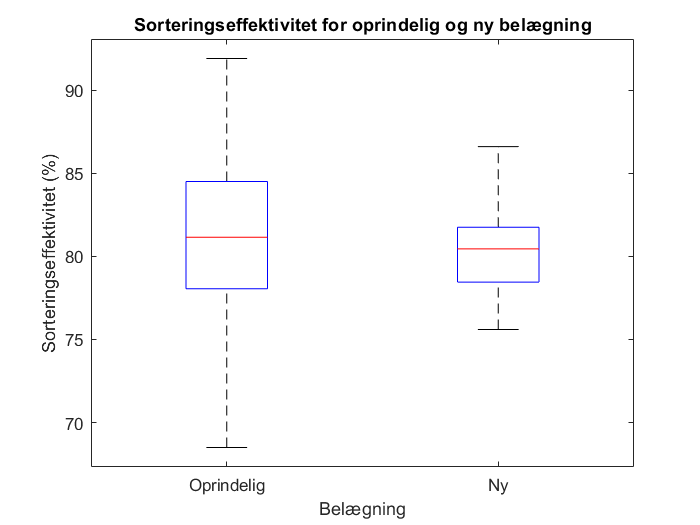

boxplot(D, 'Labels', {'Oprindelig', 'Ny'})
title('Sorteringseffektivitet for oprindelig og ny belægning')
ylabel('Sorteringseffektivitet (%)')
xlabel('Belægning')

**Forskelle på oprindelig og ny belægning: **

I a. så vi at middelværdierne er sammenlignelige for de to stikprøver (hhv. 80.7 og 80.4), men der lader til at være forskel på standardafvigelserne (hhv. 5.6 og 2.6) og dermed på varianserne. 

I b. så vi samme billede, at 95 % konfidensintervallet for oprindelig belægning var bredere end for ny (hhv. [78.3; 83.1] og [79.3; 81.5]). 

I c. viser det parallelle boksplot at medianerne er på samme niveau, men de interkvartile ranges og kostene er større for den oprindelige belægning. 

Alt i alt lader den nye belægning til at have gjort sorteringen mere ensartet og dermed mere uafhængig af fordelingen af hårdt og blødt plastik i kasserne. Det lader til at problemet med at sortere fladt, hårdt plastik er blevet løst.  

#### d. Projektgruppen vurderer, at der ikke er signifikant forskel på den gennemsnitlige sorteringseffektivitet. Derimod vil de gerne foretage en hypotesetest for, om der på 5 % signifikansniveau er forskel på varianserne. Opskriv nulhypotese og alternativhypotese for denne hypotesetest. 

Nul- og alternativhypotese: 

        H_0: sigma2_opr = sigma2_ny

        H_a: sigma2_opr <> sigma2_ny,

hvor sigma2_opr og sigma2_ny er populationsvariansen for sorteringseffektivitet af hårdt plastik med hhv. oprindelig og ny belægning

#### e. Opstil formlen for teststørrelsen og angiv, hvilken fordeling den følger. 

Formel for teststørrelsen: 

        F_0 = s2_opr / s2_ny,

hvor s2_opr og s2_ny er stikprøvevarianserne for sorteringseffektiviteten med hhv. oprindelig og ny belægning.

Teststørrelsen er F-fordelt med n-1 frihedsgrader i både tæller og nævner (da vi har samme stikprøvestørrelse i de to stikprøver, nemlig n = 24). 

#### f. Beregn den kritiske region for testen, beregn teststørrelsen og konkludér på hypotesetesten.

Kritisk region: 

Det er en to-sidet test (vi tester blot, om der er forskel på varianserne i de to stikprøver), så nulhypotesen forkastes, hvis teststørrelsen er under F_alfahalve_nedre eller over F_alfahalve_oevre, som beregnes sådan: 

alfa = 0.05

alfa = 0.0500

F_alfahalve_nedre = finv(alfa/2, n-1, n-1)      

F_alfahalve_nedre = 0.4326

F_alfahalve_oevre = finv(1-alfa/2, n-1, n-1)   

F_alfahalve_oevre = 2.3116

Teststørrelsens værdi:

F_0 = s2_opr / s2_ny 

F_0 = 4.8270

Konklusion: 

Da F_0 > F_alfahalve_oevre forkastes nulhypotesen. 

Med andre ord viser stikprøverne, at der på 5 % signifikansniveau er forskel på variansen af sorteringseffektiviteten med de to belægninger. 

Da teststørrelsen beregnes som forholdet mellem stikprøvernes varians kunne den lige så godt beregnes sådan:  

F_0 = s2_ny / s2_opr

F_0 = 0.2072

I så fald forkastes nulhypotesen ligeledes, da F_0 < F_alfahalve_nedre

#### g. Oplys hvilke antagelser, der er gjort i hypotesetesten, og om antagelserne er rimelige på baggrund af data. 

Hypotesetesten for varianser bygger på antagelsen, at observationerne i de to stikprøver begge er normalfordelte. Det er en stærkere antagelse end den Centrale Grænseværdisætning, hvor det blot antages, at data kommer fra en 'pæn' fordelingen, med mindre stikprøvestørrelsen er stor. 

Vi kan teste antagelsen med normalfordelingsplot:

Stikprøve med oprindelig belægning:

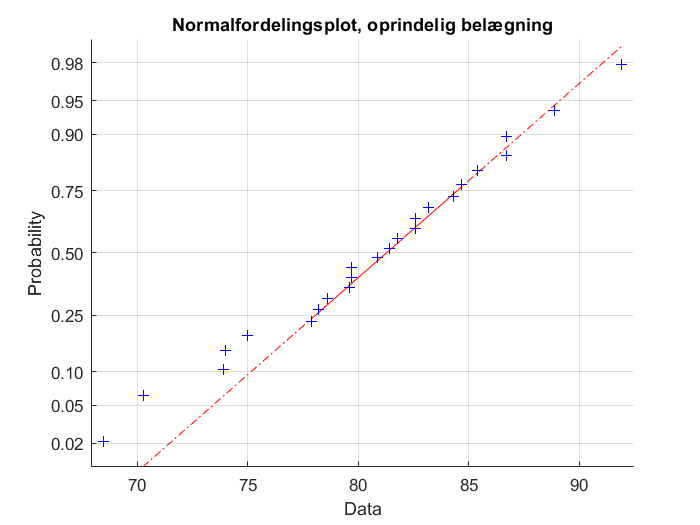

figure(1)
normplot(effekt_opr)
title('Normalfordelingsplot, oprindelig belægning')

Stikprøve med ny belægning:

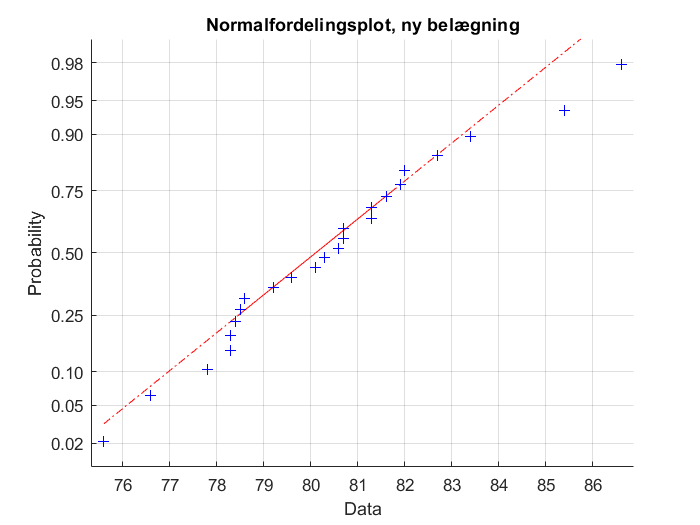

figure(2)
normplot(effekt_ny)
title('Normalfordelingsplot, ny belægning')

Begge normalfordelingsplots er nogenlunde lineære, så det lader til, at antagelsen holder. 